# jacobi - Analisi

In questo documento sono mostrate le analisi relative all'algoritmo implementato. 

# Test di accuratezza

Il software realizzato è stato testato attraverso matrici sparse di notevoli dimensioni non singolari e ben condizionate. A tale proposito, è stata utilizzata la funzione `accuracy_test(A,b,TOL,x0,MAXITER) `allegata alla documentazione, che restituisce una struttura contenente il *condizionamento* della matrice A, l'*errore relativo*, il *numero di iterazioni, *il *residuo relativo* e stampa un *grafico illustrativo* della matrice di test.

**Test con matrice A tale che **$\;\rho \left(A\right)<\;1$

Il raggio spettrale minore di 1 è una condizione sufficiente per la convergenza dell'algoritmo di Jacobi: la seguente simulazione conferma il risultato teorico.

% La matrice A è diagonale in modo che gli autovalori coincidano con 
% gli elementi della diagonale principale
n = 100;
A = spdiags(rand(n,1),0,n,n);
x = ones(n,1);
max_autovalore = max(eig(A))

max_autovalore = 0.9952

ans = struct with fields:
     condizionamento: 140.5483
     errore_relativo: 0
               niter: 2
    residuo_relativo: 0


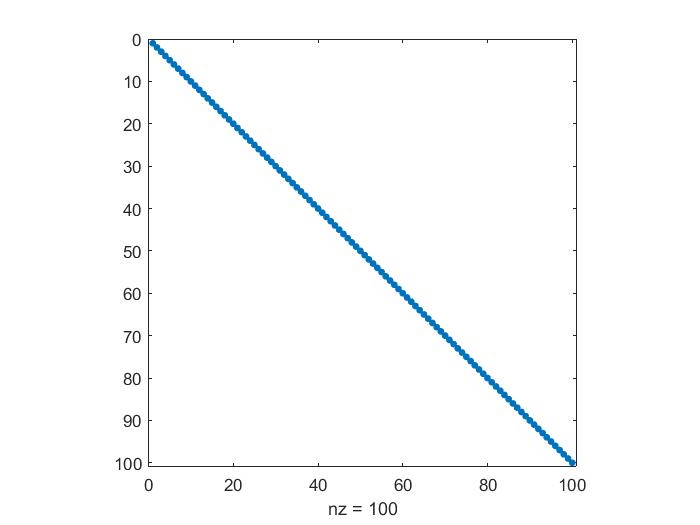

compute_accuracy(A,x,eps,zeros(n,1),1000)

**Test con matrice A a diagonale strettamente dominante**

Dato che $\rho \left(A\right)\le \left\|A\right\|$ , anche la diagonale principale dominante è una condizione sufficiente per la convergenza del metodo di Jacobi: le due simulazioni confermano il risultato.

ans = struct with fields:
     condizionamento: 6.8134
     errore_relativo: 2.4623e-08
               niter: 35
    residuo_relativo: 1.6768e-08


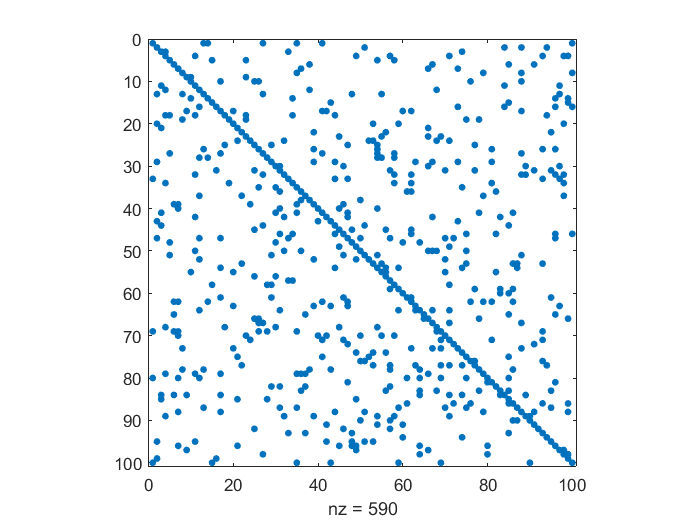

n = 100;
A=sprand(n,n,0.05)+spdiags(ones(n,1),0,n,n)*4;
x = ones(n,1);
compute_accuracy(A,x)

ans = struct with fields:
     condizionamento: 4.2857
     errore_relativo: 8.9095e-08
               niter: 26
    residuo_relativo: 3.3018e-08


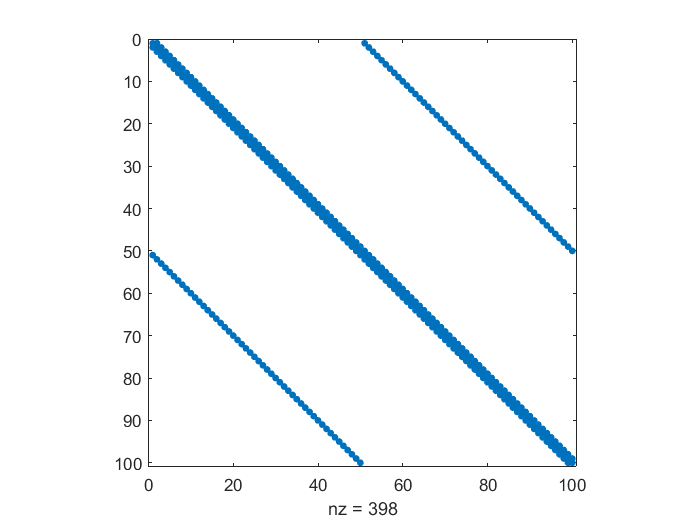

n = 100;
onesColumn = ones(n,1); diag = 6; 
columns = [onesColumn, -onesColumn, diag*onesColumn, -onesColumn, 2*onesColumn];
d = [-n/2, -1, 0, 1, n/2];
A = spdiags(columns,d,n,n);
x = ones(n,1);
compute_accuracy(A,x)

**Test con matrice A tridiagonale (dalla gallery)**

ans = struct with fields:
     condizionamento: 61.0000
     errore_relativo: 4.7909e-08
               niter: 514
    residuo_relativo: 4.7909e-08


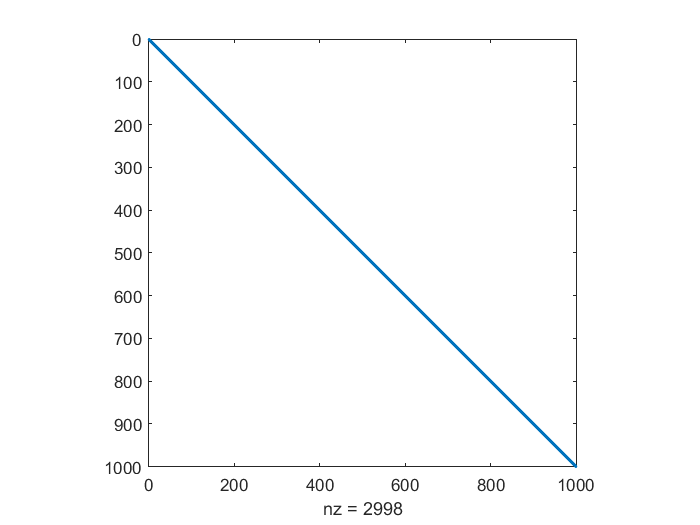

n = 1000;
A = gallery('tridiag',1000,10,31,20);
x = ones(n,1);
compute_accuracy(A,x)

**Test con matrice A di Poisson**

Su matrici di Poisson di dimensioni notevoli, si ottiene un risultato accettabile ma il numero di iterazioni che deve eseguire l'algoritmo è molto elevato:

n = 100;
A = gallery('poisson',n);
x = ones(n^2,1);
% L'algoritmo non converge con il n° di iterazioni di default:
jacobi(A,A*x); 

ans = struct with fields:
     condizionamento: 6.0107e+03
     errore_relativo: 2.0661e-04
               niter: 18534
    residuo_relativo: 1.9988e-07


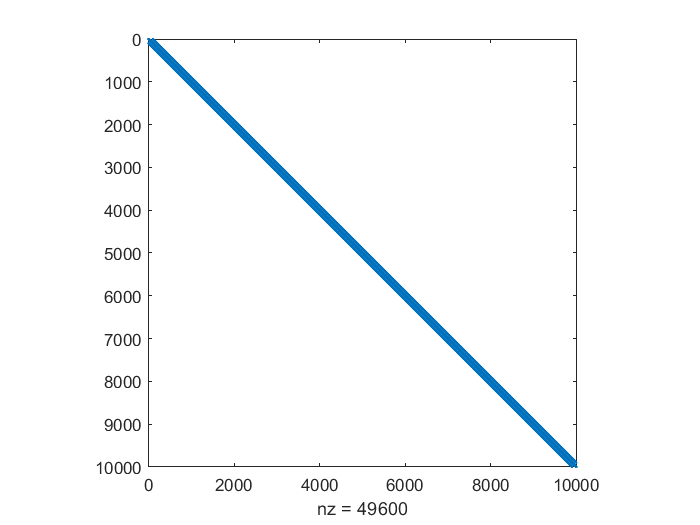

compute_accuracy(A,x,1e-7,zeros(n^2,1),20000)

*NB: il numero di cifre significative corrette nella soluzione è 4, a fronte delle 7 richieste tramite il parametro TOL. Ciò è dovuto al condizionamento della matrice dei coefficienti.*

# Robustezza

I test sono stati progettati in modo che tutte le condizioni di errore/warning più importanti fossero attivate almeno una volta. Nell'implementazione è stato usato il framework di Matlab per il testing di unità; questa scelta ha permesso di automatizzare completamente l'esecuzione dei test: infatti, è possibile lanciare la simulazione con l'istruzione:

results = runtests('test_suite.m')

Running test_suite
..........
Done test_suite
__________



results =   1×10 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   10 Passed, 0 Failed, 0 Incomplete.
   0.10992 seconds testing time.


Il sistema esegue in automatico i test, riportando in `results `un sommario di quanti hanno avuto successo e dettagliando gli errori in quelli che eventualmente sono falliti.

*N.B. Per semplicità non sono stati implementati i test relativi a dati di input che contenessero valori invalidi *`NaN/Inf`*.*

Inoltre, è presentato, di seguito, un test in cui viene forzata una condizione di *underflow* nel sistema. In particolare, tale condizione si verifica poichè il punto di partenza specificato `x0` è costituito da valori pari a `realmin,` e quindi l'operazione` TOL*x0` nella prima iterazione del ciclo genera sicuramente un underflow. Si può osservare che il risultato ottenuto è robusto rispetto all'errore, ciò dipende dal controllo implementato nella funzione `controllo_underflow.` 

ans = struct with fields:
     condizionamento: 7.7885
     errore_relativo: 4.4409e-16
               niter: 91
    residuo_relativo: 1.8404e-16


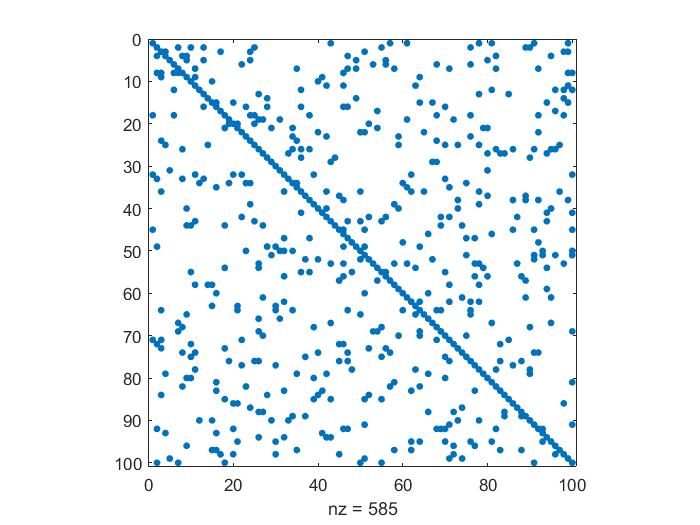

n=100;
A=sprand(n,n,0.05)+spdiags(ones(n,1),0,n,n)*4;
x=ones(100,1);
x0=x*realmin;
b=A*x;
compute_accuracy(A,x,eps,x0)

## Autori                                                                                                                          

Valerio La Gatta, Marco Postiglione